i = 11;
j = 4;
p = 18;
q = -14;
r = 12;
s = 17;

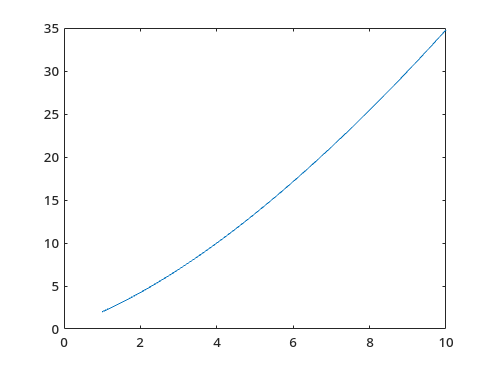

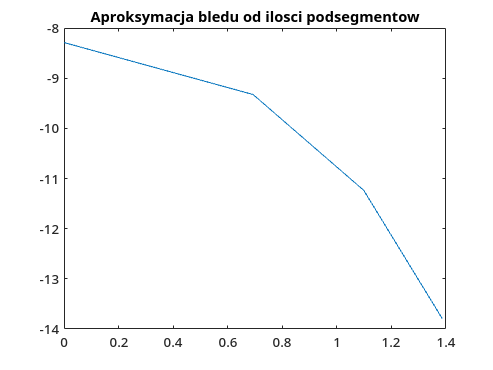

clf;
assigment1('sqrt(x).*x+sqrt(x)', 1, 10);

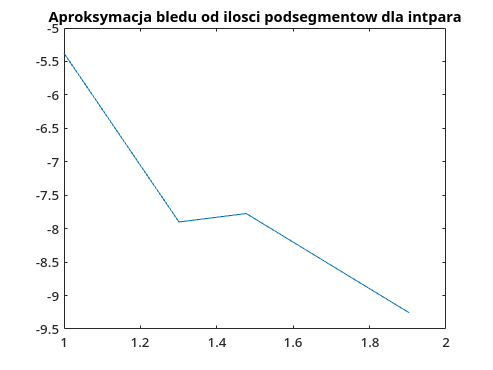

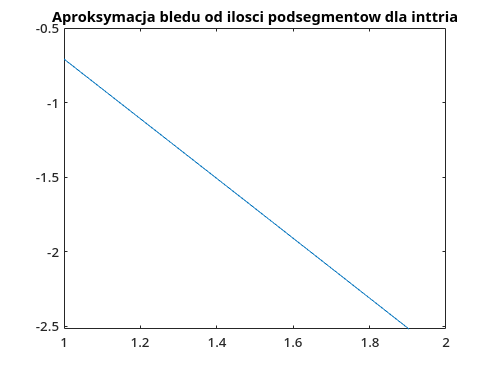

clf;
assigment3('sqrt(x).*x+sqrt(x)', 1, 10);

clf;
A = [p 1 2 3;
     1 q 8 3;
     2 8 r 9;
     3 3 9 s];

numberOfColumns = numel(nValues)-1

numberOfColumns = 4


[V, D] = eig(A)

V =    -0.0113    0.0274    0.9205    0.3895
    0.9634    0.1930   -0.0673    0.1734
   -0.2675    0.7272   -0.2673    0.5729
   -0.0135   -0.6582   -0.2768    0.7000


D =   -16.2749         0         0         0
         0    6.0523         0         0
         0         0   16.4442         0
         0         0         0   26.7785


D = diag(D);

difference = zeros(1, numberOfColumns);
for i = 1:numberOfColumns
    A.*V(:, i) 
    D(i).*V(:, i)
    difference(i) = norm(A.*V(:, i) - D(i).*V(:, i))
end

ans =    -0.2037   -0.0113   -0.0226   -0.0340
    0.9634  -13.4876    7.7072    2.8902
   -0.5350   -2.1399   -3.2098   -2.4074
   -0.0405   -0.0405   -0.1214   -0.2293


ans =     0.1842
  -15.6793
    4.3533
    0.2195


difference =    36.2315         0         0         0


ans =     0.4930    0.0274    0.0548    0.0822
    0.1930   -2.7020    1.5440    0.5790
    1.4543    5.8174    8.7260    6.5445
   -1.9746   -1.9746   -5.9238  -11.1893


ans =     0.1658
    1.1681
    4.4011
   -3.9836


difference =    36.2315    8.9418         0         0


ans =    16.5699    0.9205    1.8411    2.7616
   -0.0673    0.9420   -0.5383   -0.2018
   -0.5347   -2.1386   -3.2079   -2.4060
   -0.8303   -0.8303   -2.4909   -4.7050


ans =    15.1376
   -1.1064
   -4.3960
   -4.5512


difference =    36.2315    8.9418   23.6241         0


ans =     7.0110    0.3895    0.7790    1.1685
    0.1734   -2.4282    1.3875    0.5203
    1.1458    4.5832    6.8747    5.1561
    2.1000    2.1000    6.3000   11.9000


ans =    10.4303
    4.6445
   15.3413
   18.7449


difference =    36.2315    8.9418   23.6241   39.4732


function assigment1(f, a, b)
    numberOfNs = ceil(log2(b/a));
    errors = zeros(1, numberOfNs);
   
    i = 1;
    for n = 0:numberOfNs
        segmentLength = (b - a) / (2^n);
        c = a;
        d = a + segmentLength;
        error = lagrange(f, c, d);
        errors(i) = error;
        i = i + 1;
    end
    
    ns = 0:numberOfNs;
    plot(log(ns), log(errors));
    title('Aproksymacja bledu od ilosci podsegmentow');
end

function assigment3(f, c, d)
    nValues = [10, 20, 30, 80];
    numberOfNs = numel(nValues);
    errors = zeros(1, numberOfNs);
   
    for i = 1:numberOfNs
        n = nValues(i);
        integral = intpara(f, n, c, d);
        exactIntegral = intpara(f, 1000, c, d);
        error = abs(integral - exactIntegral);
        errors(i) = error;
    end
    
    plot(log10(nValues), log10(errors));
    title('Aproksymacja bledu od ilosci podsegmentow dla intpara');

    for i = 1:numberOfNs
        n = nValues(i);
        integral = inttria(f, n, c, d);
        exactIntegral = inttria(f, 1000, c, d);
        error = abs(integral - exactIntegral);
        errors(i) = error;
    end
    
    plot(log10(nValues), log10(errors));
    title('Aproksymacja bledu od ilosci podsegmentow dla inttria');
end

function assigment5(p, q, r, s)
    
end

function result = lagrange(f, c, d)
    %Lagrange polynomials of 4th order
    w1='(x-.25).*(x-.50).*(x-.75).*(x-1 )/(24/256)';
    w2='(x- 0).*(x-.50).*(x-.75).*(x-1 )/(-6/256)';
    w3='(x- 0).*(x-.25).*(x-.75).*(x-1 )/(4/256)';
    w4='(x- 0).*(x-.25).*(x-.50).*(x-1 )/(-6/256)';
    w5='(x- 0).*(x-.25).*(x-.50).*(x-.75)/(24/256)';
    %find values of f(x) at sampling points:
    x=0:.25:1;
    x=c+(d-c)*x;
    a=eval(f);
    %find values of Lagrangian interpolant of f(x):
    x=0:.01:1;
    y=a(1).*eval(w1)+a(2).*eval(w2)+a(3).*eval(w3)...
    +a(4).*eval(w4)+a(5).*eval(w5);
    %find values of exact function f(x):
    x=c+(d-c)*x;
    z=eval(f);
    %draw pictures:
    plot(x,y);
    plot(x,z,'m');
    %find maximum error
    y=abs(y-z);
    result = max(y);
end

function result = inttria(f, n, a, b)
    h=(b-a)/n;
    s=0;
    for i=1:n
        x=a+(i-1)*h;
        y=eval(f);
        x=x+h;
        z=eval(f);
        s=s+(y+z)*0.5*h;
    end
    result = s;
end

function result = intpara(f, n, a, b)
    h=(b-a)/n;
    s=0;
    for i=1:n
        x=a+(i-1)*h;
        y=eval(f);
        x=x+0.5*h;
        t=eval(f);
        x=x+0.5*h;
        z=eval(f);
        s=s+(y/6+2/3*t+z/6)*h;
    end
    result = s;
end